# MPC tuning with Bayesian Optimization

clc
clf
clear all
close all
rng(0)

## Parallel computing

if isempty(gcp('nocreate'))
    cluster = parcluster('local');
    parpool(cluster, cluster.NumWorkers);
end
p = gcp();
fprintf('Using %d parallel workers', p.NumWorkers);

Using 8 parallel workers

## Define optimization variables

% lambda_z = optimizableVariable('lambda_z', [1e-4, 1e-2], 'Transform', 'log');
% lambda_o = optimizableVariable('lambda_o', [1e-3, 1e-1], 'Transform', 'log');
% lambda   = optimizableVariable('lambda'  , [1e-2, 1], 'Transform', 'log');

% lambda_z = optimizableVariable('lambda_z', [1e-4, 1e-2], 'Transform', 'log');
% lambda_o = optimizableVariable('lambda_o', [1e-4, 1e-2], 'Transform', 'log');
% lambda   = optimizableVariable('lambda'  , [1e-3, 1e-1], 'Transform', 'log');

lambda_z = optimizableVariable('lambda_z', [1e-5, 1e-1], 'Transform', 'log');
lambda_o = optimizableVariable('lambda_o', [1e-5, 1e-1], 'Transform', 'log');
lambda   = optimizableVariable('lambda'  , [1e-5, 1e-1], 'Transform', 'log');

optimization_variables = [lambda_z, lambda_o, lambda];

## Bayesian optimization

Copying objective function to workers...
Done copying objective function to workers.
|==============================================================================================================================|
| Iter | Active  | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |     lambda_z |     lambda_o |       lambda |
|      | workers | result |             | runtime     | (observed)  | (estim.)    |              |              |              |
|==============================================================================================================================|
|    1 |       8 | Best   |    0.089228 |      58.806 |    0.089228 |    0.089228 |    0.0020592 |     0.015968 |   0.00069718 |
|    2 |       2 | Accept |    0.092832 |      59.227 |    0.060204 |    0.060204 |     0.030485 |     0.016514 |   3.0602e-05 |
|    3 |       2 | Accept |    0.071434 |      60.159 |    0.060204 |    0.060204 |   0.00077339 |    1.401e-05 |    0.0015023 |
|    4 |    

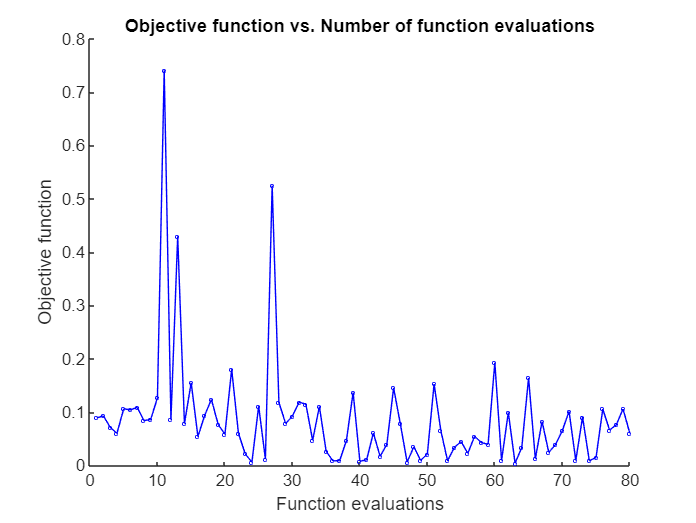

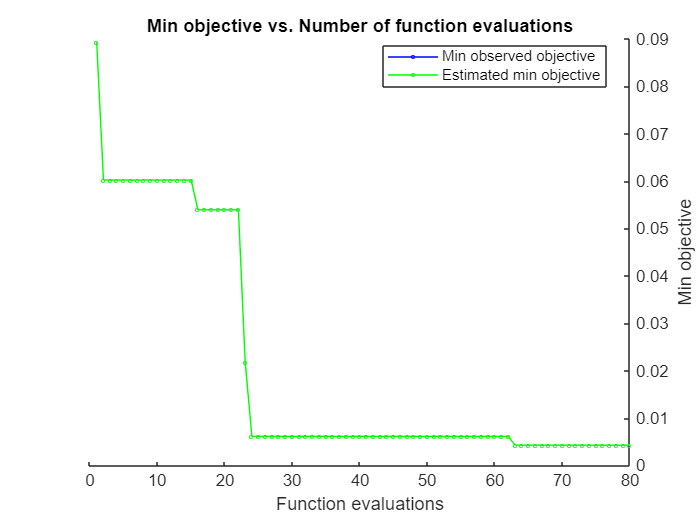

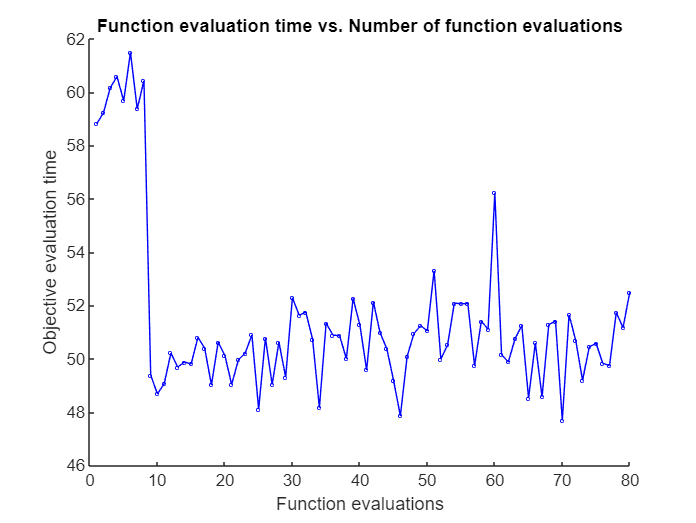

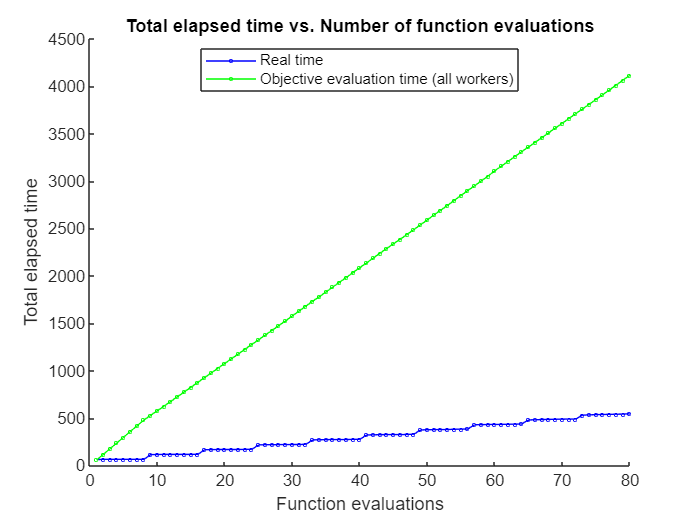

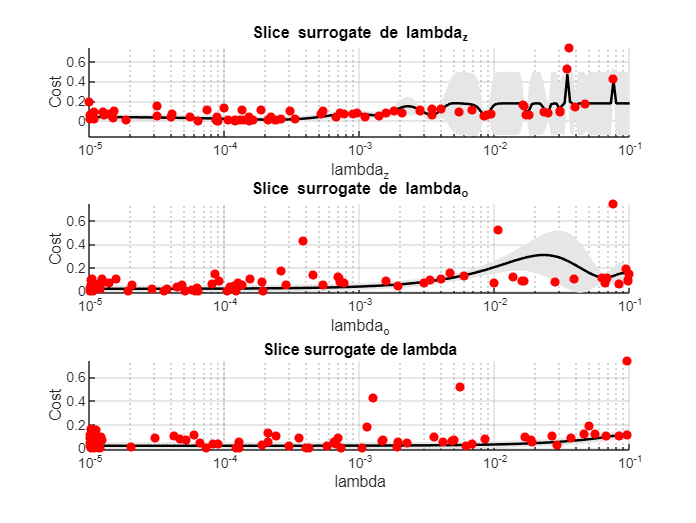


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 80 reached.
Total function evaluations: 80
Total elapsed time: 544.3073 seconds
Total objective function evaluation time: 4116.1977

Best observed feasible point:
     lambda_z      lambda_o       lambda  
    __________    __________    __________
    9.0041e-05    1.0015e-05    1.0847e-05
Observed objective function value = 0.0042821
Estimated objective function value = 0.0042821
Function evaluation time = 50.7535

Best estimated feasible point (according to models):
     lambda_z      lambda_o       lambda  
    __________    __________    __________
    9.0041e-05    1.0015e-05    1.0847e-05
Estimated objective function value = 0.0042821
Estimated function evaluation time 

results = bayesopt(@objective_function, optimization_variables, ...
    'MaxObjectiveEvaluations',   10*p.NumWorkers, ...
    'NumSeedPoints',             2*p.NumWorkers, ...
    'AcquisitionFunctionName',   'expected-improvement-plus', ...
    'IsObjectiveDeterministic',  true, ...
    'UseParallel',               true, ...
    'Verbose',                   1, ...
    'PlotFcn', {@plotObjective, @plotMinObjective, @plotObjectiveEvaluationTime, @plotElapsedTime, @plotSurrogateSlice} ...
);

## Objective function

Simulate MMCC + Induction Machine and calculate MPC mean cost

function cost = objective_function(x)
    try
        cost = simulate(x);
    catch
        cost = 10;
    end
end

## Custom plot function

Plot surrogate model

function stop = plotSurrogateSlice(results, state)
    stop = false;
    % Plot if an iteration is completed
    if ~strcmp(state, 'iteration')
        return;
    end
    % Optimization variables names
    varsDesc = results.VariableDescriptions;
    varNames = {varsDesc.Name};
    numVar = numel(varNames);
    % Fit gaussian process
    gp = fitrgp(results.XTrace, results.ObjectiveTrace, 'Standardize', true, 'KernelFunction', 'ardsquaredexponential');
    % Best estimated point
    bestEst = table2struct(results.XAtMinEstimatedObjective);
    % Observations
    Xobs = results.XTrace;
    Yobs = results.ObjectiveTrace;
    % Update slices figure
    figure(5);
    clf;
    for iVar = 1:numVar
        % log scale range
        lb = varsDesc(iVar).Range(1);
        ub = varsDesc(iVar).Range(2);
        xgrid = logspace(log10(lb), log10(ub), 200)';
        % Construct prediction table for slice
        Tpred = table();
        for jVar = 1:numVar
            nm = varNames{jVar};
            if jVar == iVar
                Tpred.(nm) = xgrid;
            else
                Tpred.(nm) = repmat(bestEst.(nm), numel(xgrid), 1);
            end
        end
        % Predict mu and sigma
        [mu, sigma] = predict(gp, Tpred);
        % Subplot
        subplot(numVar, 1, iVar);
        hold on;
        grid on;
        % Confidence bound 95%
        fill([xgrid; flipud(xgrid)], [mu+2*sigma; flipud(mu-2*sigma)], 0.9*[1 1 1], 'EdgeColor', 'none');
        % Surrogate mean
        plot(xgrid, mu, '-k', 'LineWidth', 1.5);
        % Observated values
        xi_obs = Xobs{:,iVar};
        scatter(xi_obs, Yobs, 30, 'r', 'filled');
        set(gca, 'XScale', 'log');
        xlabel(varNames{iVar});
        ylabel('Cost');
        title(sprintf('Slice surrogate de %s', varNames{iVar}));
    end
    drawnow;
end
